## Parámetros

syms q1(t) q2(t) t theta
syms m1 l1 lc1 I1 m2 l2 lc2 I2 g

## Cinematica directa y diferencial

%xy2 = @(q1,q2) [l1*cos(q1)+lc2*cos(q1+q2); l1*sin(q1)+lc2*sin(q1+q2)];
%xy2(0,pi/2)
%v1 = @(q1,vq1) [-lc1*sin(q1); lc1*cos(q1)].*vq1;
%v1(pi/2,1)
%v2 = @(q1,q2,vq1,vq2) [-l1*sin(q1)-lc2*sin(q1+q2) -lc2*sin(q1+q2); l1*cos(q1)+lc2*cos(q1+q2) lc2*cos(q1+q2)]*[vq1;vq2];
%v2(0,0,1,1)
xy1 = [lc1*cos(q1); lc1*sin(q1)]

$$xy1(t) = \left(\begin{array}{c} {\mathrm{lc}}_{1}\,\cos\left(q_{1}\left(t\right)\right)\\ {\mathrm{lc}}_{1}\,\sin\left(q_{1}\left(t\right)\right) \end{array}\right)$$

xy2 = [l1*cos(q1)+lc2*cos(q1+q2); l1*sin(q1)+lc2*sin(q1+q2)]

$$xy2(t) = \left(\begin{array}{c} l_{1}\,\cos\left(q_{1}\left(t\right)\right)+{\mathrm{lc}}_{2}\,\cos\left(q_{1}\left(t\right)+q_{2}\left(t\right)\right)\\ l_{1}\,\sin\left(q_{1}\left(t\right)\right)+{\mathrm{lc}}_{2}\,\sin\left(q_{1}\left(t\right)+q_{2}\left(t\right)\right) \end{array}\right)$$

cdE = [l1*cos(q1)+l2*cos(q1+q2); l1*sin(q1)+l2*sin(q1+q2)]

$$cdE(t) = \left(\begin{array}{c} l_{1}\,\cos\left(q_{1}\left(t\right)\right)+l_{2}\,\cos\left(q_{1}\left(t\right)+q_{2}\left(t\right)\right)\\ l_{1}\,\sin\left(q_{1}\left(t\right)\right)+l_{2}\,\sin\left(q_{1}\left(t\right)+q_{2}\left(t\right)\right) \end{array}\right)$$

v1 = diff(xy1,t)

$$v1(t) = \left(\begin{array}{c} -{\mathrm{lc}}_{1}\,\sin\left(q_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{1}\left(t\right)\\ {\mathrm{lc}}_{1}\,\cos\left(q_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{1}\left(t\right) \end{array}\right)$$

v2 = diff(xy2,t)

$$v2(t) = \left(\begin{array}{c} -{\mathrm{lc}}_{2}\,\sin\left(q_{1}\left(t\right)+q_{2}\left(t\right)\right)\,\left(\frac{\partial }{\partial t}q_{1}\left(t\right)+\frac{\partial }{\partial t}q_{2}\left(t\right)\right)-l_{1}\,\sin\left(q_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{1}\left(t\right)\\ {\mathrm{lc}}_{2}\,\cos\left(q_{1}\left(t\right)+q_{2}\left(t\right)\right)\,\left(\frac{\partial }{\partial t}q_{1}\left(t\right)+\frac{\partial }{\partial t}q_{2}\left(t\right)\right)+l_{1}\,\cos\left(q_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{1}\left(t\right) \end{array}\right)$$

## Energía Cinética

K = 1/2*(m1*transpose(v1)*v1 + I1*diff(q1,t)^2 + m2*transpose(v2)*v2 + I2*(diff(q1,t)+diff(q2,t))^2)

$$K(t) = \begin{array}{l} \frac{m_{2}\,{\left({\mathrm{lc}}_{2}\,\cos\left(\sigma_{3}\right)\,\sigma_{1}+l_{1}\,\cos\left(q_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{1}\left(t\right)\right)}^{2}}{2}+\frac{m_{2}\,{\left({\mathrm{lc}}_{2}\,\sin\left(\sigma_{3}\right)\,\sigma_{1}+l_{1}\,\sin\left(q_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{1}\left(t\right)\right)}^{2}}{2}+\frac{I_{1}\,\sigma_{2}}{2}+\frac{I_{2}\,{\sigma_{1}}^{2}}{2}+\frac{{{\mathrm{lc}}_{1}}^{2}\,m_{1}\,{\cos\left(q_{1}\left(t\right)\right)}^{2}\,\sigma_{2}}{2}+\frac{{{\mathrm{lc}}_{1}}^{2}\,m_{1}\,{\sin\left(q_{1}\left(t\right)\right)}^{2}\,\sigma_{2}}{2}\\ \mathrm{where}\\ \sigma_{1}=\frac{\partial }{\partial t}q_{1}\left(t\right)+\frac{\partial }{\partial t}q_{2}\left(t\right)\\ \sigma_{2}={\left(\frac{\partial }{\partial t}q_{1}\left(t\right)\right)}^{2}\\ \sigma_{3}=q_{1}\left(t\right)+q_{2}\left(t\right) \end{array}$$

% Compute simplified symbolic expression
K

$$K(t) = \begin{array}{l} \frac{m_{2}\,{\left({\mathrm{lc}}_{2}\,\cos\left(\sigma_{3}\right)\,\sigma_{1}+l_{1}\,\cos\left(q_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{1}\left(t\right)\right)}^{2}}{2}+\frac{m_{2}\,{\left({\mathrm{lc}}_{2}\,\sin\left(\sigma_{3}\right)\,\sigma_{1}+l_{1}\,\sin\left(q_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{1}\left(t\right)\right)}^{2}}{2}+\frac{I_{1}\,\sigma_{2}}{2}+\frac{I_{2}\,{\sigma_{1}}^{2}}{2}+\frac{{{\mathrm{lc}}_{1}}^{2}\,m_{1}\,{\cos\left(q_{1}\left(t\right)\right)}^{2}\,\sigma_{2}}{2}+\frac{{{\mathrm{lc}}_{1}}^{2}\,m_{1}\,{\sin\left(q_{1}\left(t\right)\right)}^{2}\,\sigma_{2}}{2}\\ \mathrm{where}\\ \sigma_{1}=\frac{\partial }{\partial t}q_{1}\left(t\right)+\frac{\partial }{\partial t}q_{2}\left(t\right)\\ \sigma_{2}={\left(\frac{\partial }{\partial t}q_{1}\left(t\right)\right)}^{2}\\ \sigma_{3}=q_{1}\left(t\right)+q_{2}\left(t\right) \end{array}$$

simplifiedExpr = simplify(K)

$$simplifiedExpr(t) = \begin{array}{l} \frac{I_{1}\,\sigma_{1}}{2}+\frac{I_{2}\,\sigma_{1}}{2}+\frac{I_{2}\,\sigma_{2}}{2}+I_{2}\,\frac{\partial }{\partial t}q_{2}\left(t\right)\,\frac{\partial }{\partial t}q_{1}\left(t\right)+\frac{{l_{1}}^{2}\,m_{2}\,\sigma_{1}}{2}+\frac{{{\mathrm{lc}}_{1}}^{2}\,m_{1}\,\sigma_{1}}{2}+\frac{{{\mathrm{lc}}_{2}}^{2}\,m_{2}\,\sigma_{1}}{2}+\frac{{{\mathrm{lc}}_{2}}^{2}\,m_{2}\,\sigma_{2}}{2}+{{\mathrm{lc}}_{2}}^{2}\,m_{2}\,\frac{\partial }{\partial t}q_{2}\left(t\right)\,\frac{\partial }{\partial t}q_{1}\left(t\right)+l_{1}\,{\mathrm{lc}}_{2}\,m_{2}\,\cos\left(q_{2}\left(t\right)\right)\,\sigma_{1}+l_{1}\,{\mathrm{lc}}_{2}\,m_{2}\,\cos\left(q_{2}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{2}\left(t\right)\,\frac{\partial }{\partial t}q_{1}\left(t\right)\\ \mathrm{where}\\ \sigma_{1}={\left(\frac{\partial }{\partial t}q_{1}\left(t\right)\right)}^{2}\\ \sigma_{2}={\left(\frac{\partial }{\partial t}q_{2}\left(t\right)\right)}^{2} \end{array}$$

## Energía Potencial

U = m1*g*lc1*sin(q1) + m2*g*(l1*sin(q1)+lc2*sin(q1+q2))

$$U(t) = g\,m_{2}\,\left(l_{1}\,\sin\left(q_{1}\left(t\right)\right)+{\mathrm{lc}}_{2}\,\sin\left(q_{1}\left(t\right)+q_{2}\left(t\right)\right)\right)+g\,{\mathrm{lc}}_{1}\,m_{1}\,\sin\left(q_{1}\left(t\right)\right)$$

## Parámetros

% Eslabón 1
m1 = 0.239 %0.121 %kg

m1 = 0.2390

l1 = 0.190 %m

l1 = 0.1900

lc1 = 0.140  %0.095 %m

lc1 = 0.1400

I1 =  9.2E-4  %Nms^2 4.1E-4

I1 = 9.2000e-04


% Eslabón 2
m2 = 0.134 %kg 

m2 = 0.1340

l2 = 0.180 %m

l2 = 0.1800

lc2 = 0.098 %m

lc2 = 0.0980

I2 = 3.6E-4 %Nms^2

I2 = 3.6000e-04


g = 9.81 %m/s^2

g = 9.8100

### Matriz de inercia

cm11_1 = I1 + I2 + m1*lc1^2 + m2*l1^2 + m2*lc2^2

cm11_1 = 0.0121

cm11_2 = 2*l1*lc2*m2

cm11_2 = 0.0050

cm12_1 = I2 + lc2^2*m2

cm12_1 = 0.0016

cm12_2 = l1*lc2*m2

cm12_2 = 0.0025

cm22 = I2+m2*lc2^2

cm22 = 0.0016


M = @(q2) [cm11_1+cm11_2*cos(q2) cm12_1+cm12_2*cos(q2)
    cm12_1+cm12_2*cos(q2) cm22]

M = function_handle with value:
    @(q2)[cm11_1+cm22*cos(q2),cm12_1+cm12_2*cos(q2);cm12_1+cm12_2*cos(q2),cm22]


### Vector de pares gravitacionales

G = [diff(U,q1); diff(U,q2)]

$$G(t) = \left(\begin{array}{c} g\,m_{2}\,\left(l_{1}\,\cos\left(q_{1}\left(t\right)\right)+{\mathrm{lc}}_{2}\,\cos\left(q_{1}\left(t\right)+q_{2}\left(t\right)\right)\right)+g\,{\mathrm{lc}}_{1}\,m_{1}\,\cos\left(q_{1}\left(t\right)\right)\\ g\,{\mathrm{lc}}_{2}\,m_{2}\,\cos\left(q_{1}\left(t\right)+q_{2}\left(t\right)\right) \end{array}\right)$$


G = @(q1,q2) [g*m2*l1*cos(q1)+g*m2*lc2*cos(q1+q2)+g*lc1*m1*cos(q1)
    g*lc2*m2*cos(q1+q2)]

G = function_handle with value:
    @(q1,q2)[g*m2*l1*cos(q1)+g*m2*lc2*cos(q1+q2)+g*lc1*m1*cos(q1);g*lc2*m2*cos(q1+q2)]


### Matriz de fuerzas centrípetas y de Coriolis

M_sym = [cm11_1+cm22*cos(q2) cm12_1+cm12_2*cos(q2)
    cm12_1+cm12_2*cos(q2) cm22]

$$M\_sym(t) = \left(\begin{array}{cc} \frac{3797575862222365\,\cos\left(q_{2}\left(t\right)\right)}{2305843009213693952}+\frac{6968681848957479}{576460752303423488} & \frac{719157846928613\,\cos\left(q_{2}\left(t\right)\right)}{288230376151711744}+\frac{3797575862222365}{2305843009213693952}\\ \frac{719157846928613\,\cos\left(q_{2}\left(t\right)\right)}{288230376151711744}+\frac{3797575862222365}{2305843009213693952} & \frac{3797575862222365}{2305843009213693952} \end{array}\right)$$

Mdot = diff(M_sym,t)

$$Mdot(t) = \left(\begin{array}{cc} -\frac{3797575862222365\,\sin\left(q_{2}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{2}\left(t\right)}{2305843009213693952} & -\frac{719157846928613\,\sin\left(q_{2}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{2}\left(t\right)}{288230376151711744}\\ -\frac{719157846928613\,\sin\left(q_{2}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{2}\left(t\right)}{288230376151711744} & 0 \end{array}\right)$$

Mdote = Mdot(t)

$$Mdote = \left(\begin{array}{cc} -\frac{3797575862222365\,\sin\left(q_{2}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{2}\left(t\right)}{2305843009213693952} & -\frac{719157846928613\,\sin\left(q_{2}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{2}\left(t\right)}{288230376151711744}\\ -\frac{719157846928613\,\sin\left(q_{2}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{2}\left(t\right)}{288230376151711744} & 0 \end{array}\right)$$

C_sym = [Mdote(1,1)/2 Mdote(1,2)+Mdote(2,1)
    Mdote(1,2)+Mdote(2,1) Mdote(2,2)/2]

$$C\_sym = \left(\begin{array}{cc} -\frac{3797575862222365\,\sin\left(q_{2}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{2}\left(t\right)}{4611686018427387904} & -\frac{719157846928613\,\sin\left(q_{2}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{2}\left(t\right)}{144115188075855872}\\ -\frac{719157846928613\,\sin\left(q_{2}\left(t\right)\right)\,\frac{\partial }{\partial t}q_{2}\left(t\right)}{144115188075855872} & 0 \end{array}\right)$$

C = @(q2, vq2) [ (1/2*m2*lc2^2+I2)*sin(q2)*vq2  -2*l1*lc2*m2*sin(q2)*vq2
    -2*l1*lc2*m2*sin(q2)*vq2 0]

C = function_handle with value:
    @(q2,vq2)[(1/2*m2*lc2^2+I2)*sin(q2)*vq2,-2*l1*lc2*m2*sin(q2)*vq2;-2*l1*lc2*m2*sin(q2)*vq2,0]


## Cinemática Inversa

ci_q2 = @(x,y) acos((x.^2+y.^2-l1^2-l2^2)/(2*l1*l2))

ci_q2 = function_handle with value:
    @(x,y)acos((x.^2+y.^2-l1^2-l2^2)/(2*l1*l2))


ci_q1 = @(x,y,q2) atan2(y,x) - atan2(l2.*sin(q2),l1+l2.*cos(q2))

ci_q1 = function_handle with value:
    @(x,y,q2)atan2(y,x)-atan2(l2.*sin(q2),l1+l2.*cos(q2))


# Torque

tau = @(q1, q2, vq1, vq2, aq1, aq2) M(q2)*[aq1; aq2] + C(q2,vq2)*[vq1; vq2] + G(q1,q2)

tau = function_handle with value:
    @(q1,q2,vq1,vq2,aq1,aq2)M(q2)*[aq1;aq2]+C(q2,vq2)*[vq1;vq2]+G(q1,q2)


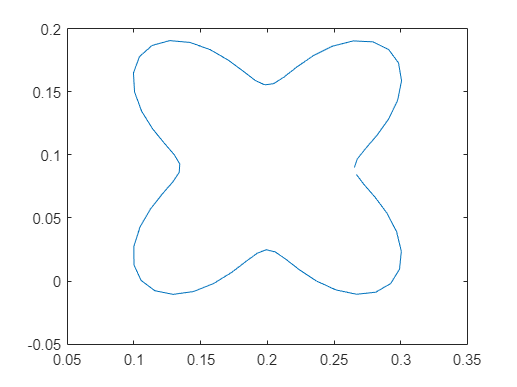

syms theta
a = 3.2604;
k = 3;
b = 1;
r = a*k+a*cos(4*theta+b*pi);
x = (r.*cos(theta) + 20)/100;
y = (r.*sin(theta) + 9)/100;

theta = 0:0.1:2*pi;
x = double(subs(x));
y = double(subs(y));
plot(x,y);

t_total = 10

t_total = 10

t = 0:t_total/62:t_total

t =          0    0.1613    0.3226    0.4839    0.6452    0.8065    0.9677    1.1290    1.2903    1.4516    1.6129    1.7742    1.9355    2.0968    2.2581    2.4194    2.5806    2.7419    2.9032    3.0645    3.2258    3.3871    3.5484    3.7097    3.8710    4.0323    4.1935    4.3548    4.5161    4.6774    4.8387    5.0000    5.1613    5.3226    5.4839    5.6452    5.8065    5.9677    6.1290    6.2903    6.4516    6.6129    6.7742    6.9355    7.0968    7.2581    7.4194    7.5806    7.7419    7.9032


q2 = ci_q2(x,y)

q2 =     1.4250    1.3887    1.3141    1.2055    1.0729    0.9332    0.8120    0.7435    0.7562    0.8480    0.9892    1.1476    1.2998    1.4306    1.5320    1.6023    1.6456    1.6697    1.6842    1.6982    1.7200    1.7557    1.8088    1.8790    1.9614    2.0471    2.1241    2.1812    2.2127    2.2226    2.2229    2.2290    2.2528    2.2999    2.3678    2.4469    2.5222    2.5756    2.5917    2.5660    2.5065    2.4268    2.3384    2.2501    2.1685    2.0984    2.0416    1.9959    1.9541    1.9058


vq2 = [0 diff(q2)./diff(t)]

vq2 =          0   -0.2255   -0.4622   -0.6733   -0.8220   -0.8663   -0.7514   -0.4246    0.0787    0.5689    0.8752    0.9823    0.9435    0.8111    0.6285    0.4360    0.2684    0.1496    0.0896    0.0872    0.1351    0.2214    0.3292    0.4351    0.5112    0.5310    0.4772    0.3540    0.1958    0.0610    0.0021    0.0374    0.1481    0.2920    0.4207    0.4905    0.4669    0.3313    0.0998   -0.1599   -0.3683   -0.4944   -0.5482   -0.5477   -0.5058   -0.4346   -0.3518   -0.2835   -0.2591   -0.2993


aq2 = [0 diff(vq2)./diff(t)]

aq2 =          0   -1.3981   -1.4672   -1.3089   -0.9224   -0.2741    0.7122    2.0259    3.1209    3.0389    1.8992    0.6637   -0.2402   -0.8213   -1.1317   -1.1936   -1.0391   -0.7366   -0.3723   -0.0147    0.2968    0.5355    0.6684    0.6563    0.4721    0.1225   -0.3331   -0.7641   -0.9806   -0.8357   -0.3655    0.2192    0.6859    0.8921    0.7981    0.4326   -0.1458   -0.8410   -1.4355   -1.6096   -1.2927   -0.7814   -0.3335    0.0032    0.2594    0.4415    0.5135    0.4235    0.1511   -0.2489


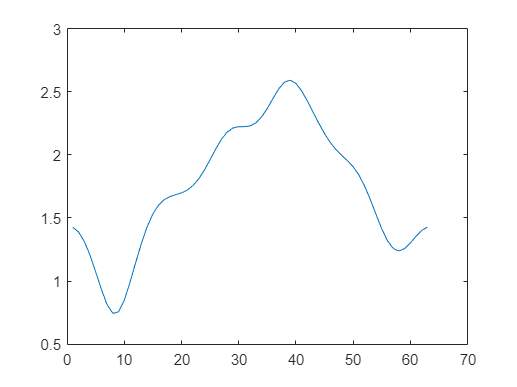

plot(q2);

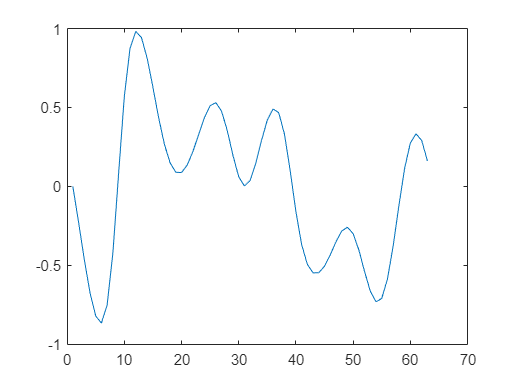

plot(vq2);

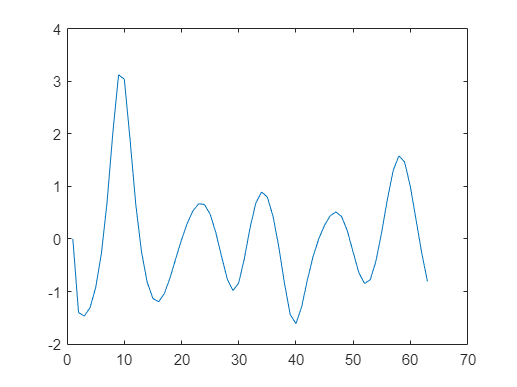

plot(aq2);


q1 = ci_q1(x,y,q2)

q1 =    -0.3620   -0.3247   -0.2700   -0.1959   -0.1046   -0.0042    0.0917    0.1638    0.1955    0.1849    0.1438    0.0857    0.0215   -0.0398   -0.0898   -0.1210   -0.1285   -0.1113   -0.0733   -0.0221    0.0328    0.0810    0.1131    0.1213    0.1002    0.0477   -0.0336   -0.1346   -0.2395   -0.3318   -0.4031   -0.4555   -0.4985   -0.5430   -0.5997   -0.6785   -0.7874   -0.9264   -1.0739   -1.1878   -1.2373   -1.2228   -1.1632   -1.0808   -0.9944   -0.9185   -0.8629   -0.8324   -0.8255   -0.8340


vq1 = [0 diff(q1)./diff(t)]

vq1 =          0    0.2316    0.3387    0.4597    0.5657    0.6229    0.5942    0.4473    0.1967   -0.0657   -0.2552   -0.3602   -0.3980   -0.3800   -0.3100   -0.1935   -0.0460    0.1065    0.2354    0.3177    0.3401    0.2990    0.1990    0.0507   -0.1307   -0.3254   -0.5044   -0.6261   -0.6502   -0.5724   -0.4417   -0.3252   -0.2662   -0.2762   -0.3517   -0.4881   -0.6753   -0.8621   -0.9145   -0.7061   -0.3069    0.0902    0.3691    0.5110    0.5358    0.4706    0.3444    0.1892    0.0432   -0.0531


aq1 = [0 diff(vq1)./diff(t)]

aq1 =          0    1.4357    0.6644    0.7501    0.6575    0.3547   -0.1785   -0.9106   -1.5539   -1.6268   -1.1751   -0.6505   -0.2344    0.1113    0.4340    0.7225    0.9143    0.9455    0.7991    0.5103    0.1391   -0.2546   -0.6202   -0.9193   -1.1249   -1.2071   -1.1095   -0.7548   -0.1492    0.4820    0.8106    0.7221    0.3660   -0.0622   -0.4681   -0.8452   -1.1609   -1.1581   -0.3246    1.2918    2.4754    2.4616    1.7292    0.8800    0.1534   -0.4038   -0.7828   -0.9618   -0.9055   -0.5970


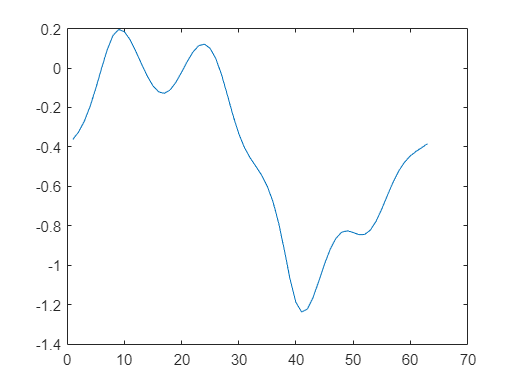

plot(q1);

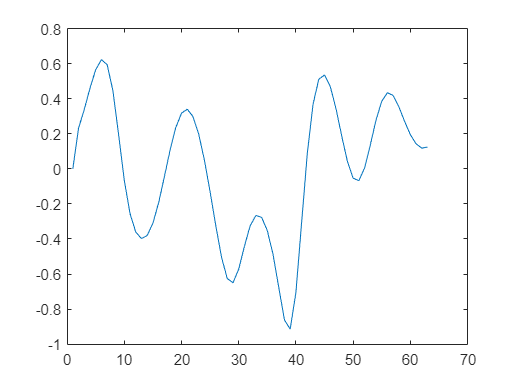

plot(vq1);

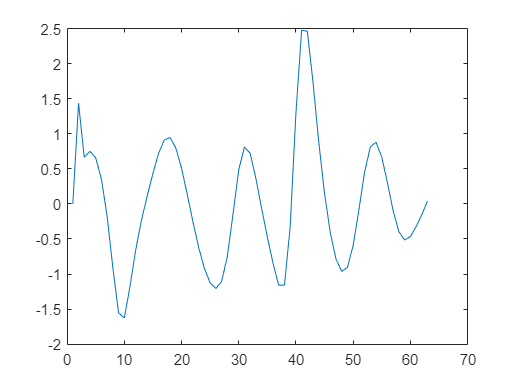

plot(aq1);


TAU = zeros(2,63)

TAU =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


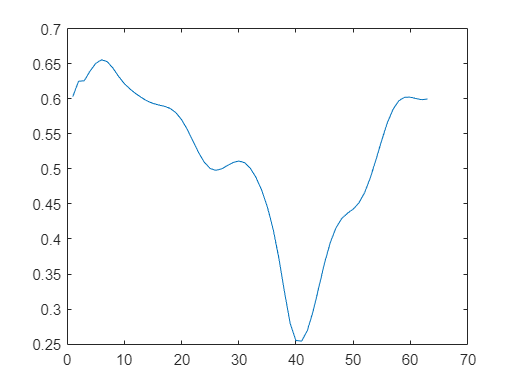

for i = 1:63
    TAU(:,i) = tau(q1(i),q2(i),vq1(i),vq2(i),aq1(i),aq2(i));
end
plot(TAU(1,:))

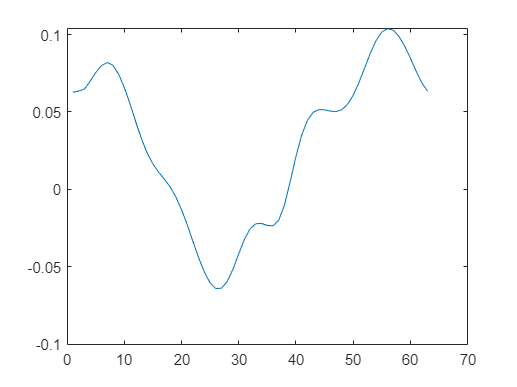

plot(TAU(2,:))